# Znamenke

% znamenke

clear
clc

load azip   % 16 x 16 bitmape vekorizirane u 256 x 1 stupce od A
load dzip   % dzip(i) = j <=> i-stupac od A sadrzi znamenku j

A = azip ; % A(:,i) je 256 x 1 = vektorizirana slika znamenke rez. 16 x 16
D = dzip ; % D(i) je 0, ..., 9; oznacava koja znamenka je u A(:,i)
% podaci za testiranje
load testzip % 16 x 16 bitmape vekorizirane u 256 x 1 stupce od A1
load dtest   % dzip(i) = j <=> i-stupac od A1 sadrzi znamenku j
A1 = testzip ;
D1 = dtest   ;

# PCA

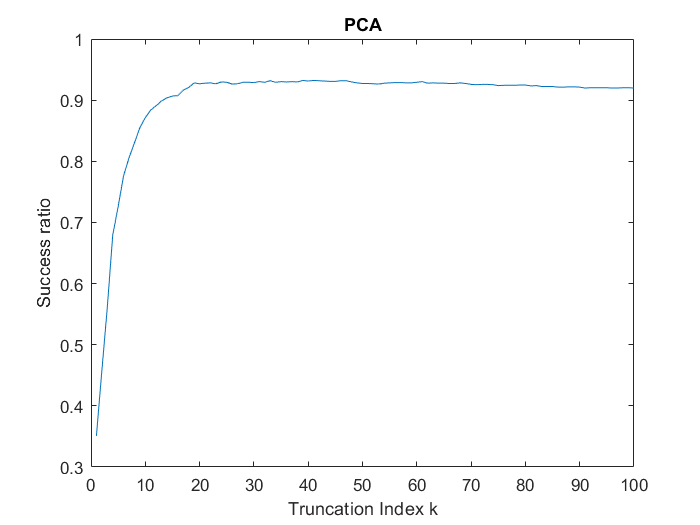

graf = zeros(100,1);
%parfor k = 1:100
%graf(k) = MatrixPCA(A, A1, k, D, D1); % spremi graf jer je spor ko blato
%end
load('PCA_znam_graph.mat')
plot(graf);
title('PCA')
xlabel('Truncation Index k')
ylabel('Success ratio')

# T-SVD

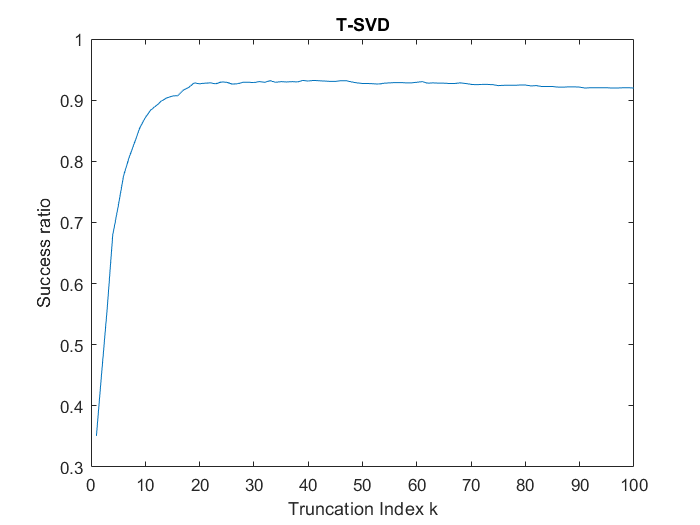

[mA,nA] = size(A) ;
for i = 1 : nA
    TA(:,i,:) = reshape( A(:,i), 16, 16 ) ;
end
[mA1,nA1] = size(A1) ;
for i = 1 : nA1
    TA1(:,i,:) = reshape( A1(:,i), 16, 16 ) ;
end

ks = [4 6 13 7 4 7 6 2 4 6];
%FaceRecognition_tSVD1(TA, TA1, ks, D, D1);
title('T-SVD')
xlabel('Truncation Index k')
ylabel('Success ratio')

# QR

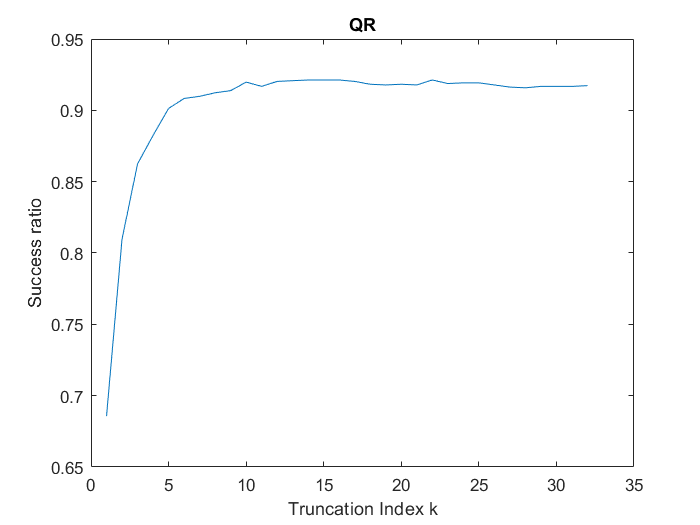

graf = zeros(32, 1);
U = tQR(TA);
% parfor k = 1:32
%     % za tSVD_ver2 novi U za svaki k
%     graf(k) = FaceRecognition_tSVD1_ver2(TA, TA1, k, D, D1, U);
% end
load('QR_znam_graph.mat')
plot(graf);
title('QR')
xlabel('Truncation Index k')
ylabel('Success ratio')

# FACES

clear
clc

load('YaleB_32x32.mat');

[nSmp,nFea] = size(fea);
% normalizacija
parfor i = 1:nSmp
    fea(i,:) = fea(i,:) ./ max(1e-12,norm(fea(i,:)));
end
str = ['50Train/17.mat'];
load(str);
fea_Train = fea(trainIdx,:);
fea_Test = fea(testIdx,:);

gnd_Train = gnd(trainIdx);
gnd_Test = gnd(testIdx);

# PCA

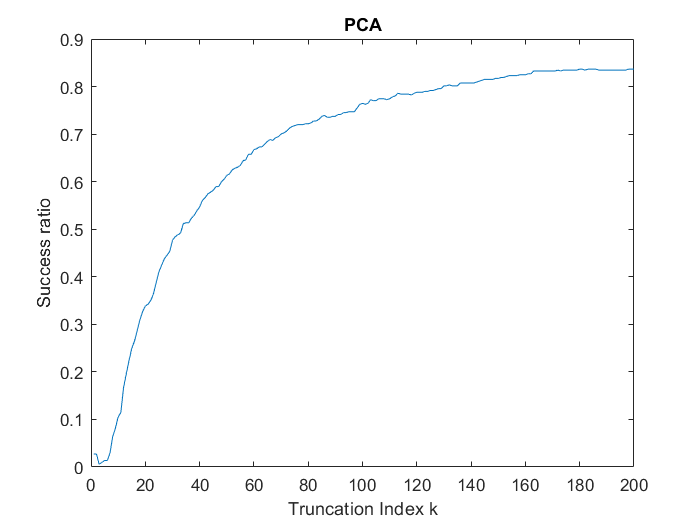


graf = zeros(100,1);
parfor k = 1:200
    graf(k) = MatrixPCA( fea_Train', fea_Test', k, gnd_Train, gnd_Test );
end
plot(graf);
title('PCA')
xlabel('Truncation Index k')
ylabel('Success ratio')

# T-SVD

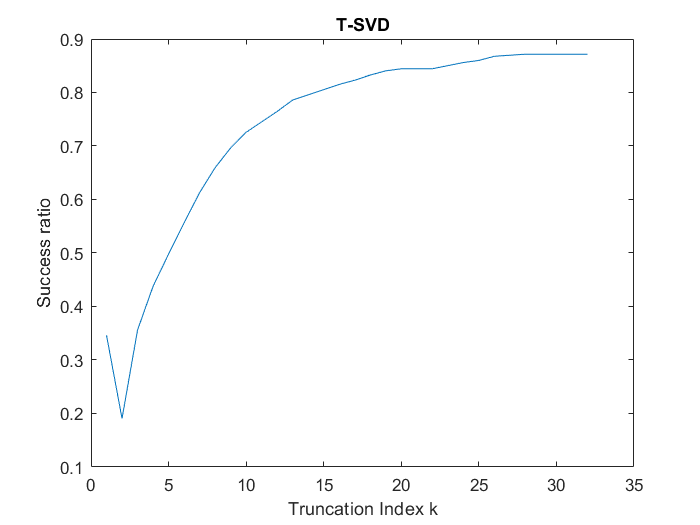

cnt1 = 1;
cnt2 = 1;
for i = 1 : size(fea,1)
    if ismember(i,trainIdx)
        TA(:,cnt1,:) = reshape(fea_Train(cnt1,:),[32,32]) ;
        cnt1 = cnt1 + 1;
    else
        TJ(:,cnt2,:) = reshape(fea_Test(cnt2,:),[32,32]) ;
        cnt2 = cnt2 + 1;
    end
end
graf = zeros(32,1);
parfor k = 1:32
    U = T_SVD(TA,k);
    percentage = FaceRecognition_tSVD1_ver2( TA, TJ, k, gnd_Train, gnd_Test, U );
    graf(k) = percentage;
end
plot(graf)
title('T-SVD')
xlabel('Truncation Index k')
ylabel('Success ratio')

# QR

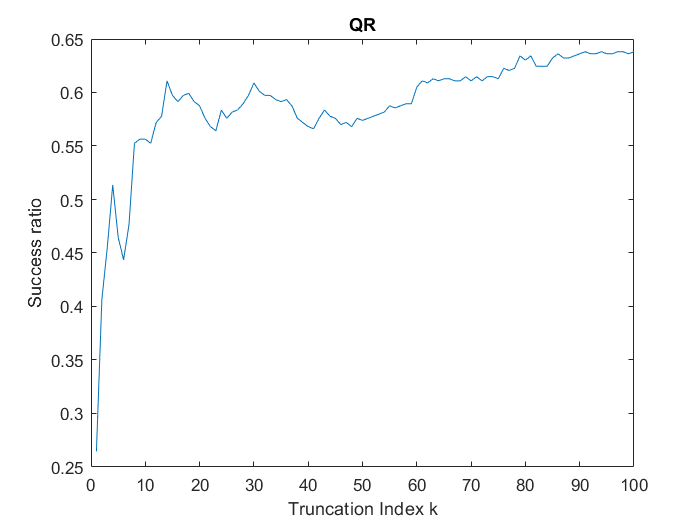


graf = zeros(100,1);
U = tQR(TA);
parfor k = 1:100
    percentage = FaceRecognition_tSVD1_ver2( TA, TJ, k, gnd_Train, gnd_Test, U );
    graf(k) = percentage;
end
% load('qr_faces_graph.mat')
plot(graf)
title('QR')
xlabel('Truncation Index k')
ylabel('Success ratio')